# Powertrain simulation in code

## Output power initialization

restoredefaultpath;
currentpath = pwd;
currentfolder = strsplit(currentpath,filesep);
while ((~strcmp(currentfolder{end}, 'EMS-aircraft')) && ...
        (~strcmp(currentfolder{end}, 'EMS-aircraft-main')) && ...
        ~isempty(currentfolder{end}))
currentpath = fileparts(currentpath);
currentfolder = strsplit(currentpath,filesep);
end
projectpath = currentpath;
addpath(genpath(projectpath));
clear projectpath currentpath currentfolder

load load_to_test_2
old_w = str2double(to_try.power)';
old_t = str2double(to_try.time)'/2;
t = 0:1e-3:old_t(end);
w = fixpt_interp1(old_t,old_w,t,float('single'),[],float('single'),[],'Floor');
clear old_w old_t to_try XTest YTest

## Powertrain simulation

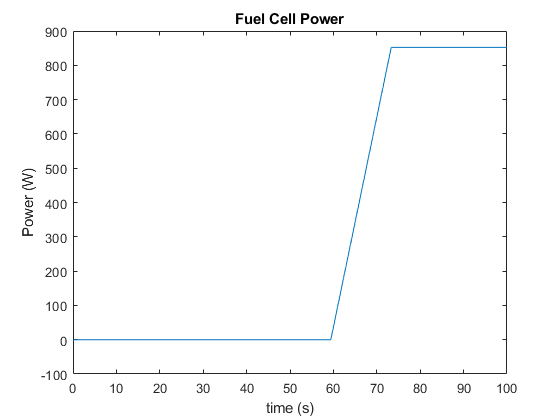

Ts = 1e-3; % Sample time
[BATTdata,FCdata,PVdata,SCdata] = init_sources(Ts); % init data sources % SOC set at 80
SimTime = 100; % Max simulation time
Vdc_wanted = 72;
Isc = 0;
Ifc = 0.001;
Ibatt = 0;
Res_sc = w(1);
Res_fc = w(1);
Res_batt = w(1);
% init sc 
[Esc,SCdata] = sc_model(Isc,SCdata);
Isc = Esc/(SCdata.Rdc+R);

power_fc = zeros(1,SimTime/Ts);
current_fc = zeros(1,SimTime/Ts);
voltage_fc = zeros(1,SimTime/Ts);
power_batt = zeros(1,SimTime/Ts);
current_batt = zeros(1,SimTime/Ts);
voltage_batt = zeros(1,SimTime/Ts);
soc_batt = zeros(1,SimTime/Ts);
current_sc = zeros(1,SimTime/Ts);
voltage_sc = zeros(1,SimTime/Ts);
soc_sc = zeros(1,SimTime/Ts);
test = zeros(1,SimTime/Ts);

alpha = dT/(Rout*(C1+C2+C3)+dT);
Ppv_out = 140;
time_vector = 0:Ts:SimTime-Ts;
for i=1:1:SimTime/Ts
    %     sprintf("sample : %.0f", i/Ts)
    Pout_required = (w(i)-Ppv_out);
    
    % part sim model
    if w(i+1)-Ppv_out > 0
        [FCdata] = fuel_cell_model(Ifc,FCdata);
        Ifc = (Pout_required/0.9)/FCdata.Efc;
    end
    [BATTdata] = battery_model(Ibatt,BATTdata);
    
    Res_batt = (BATTdata.voltage ^2)/(Pout_required/0.9)-BATTdata.R;
    
    %% fc
    % current
    %     Ifc = FCdata.Efc/Res;
    
    % arrays
%     voltage_fc(i) = FCdata.Efc;
%     current_fc(i) = Ifc;
    power_fc(i) = Ifc*FCdata.Efc;
    
    
    %% batt
    % current
    Ibatt = BATTdata.voltage/(BATTdata.R+Res_batt);
    BATTdata.ouput_voltage = BATTdata.voltage*Res_batt/(BATTdata.R+Res_batt);
    
    % arrays
%     voltage_batt(i) = BATTdata.ouput_voltage;
%     current_batt(i) = Ibatt;
    power_batt(i) = BATTdata.ouput_voltage*Ibatt;
    soc_batt(i) = BATTdata.SOC;
    
    
    Ts = 1e-3;


    [Esc,SCdata] = sc_model(Isc,SCdata);
    Isc = Esc/(SCdata.Rdc+Res_sc);
    voltage_sc(i) = Isc*Res_sc;
    current_sc(i) = Isc;
    soc_sc(i) = SCdata.SOC;

end

% new_plot(time_vector,voltage_fc,'Fuel Cell Voltage', 'time (s)', 'Voltage (V)')
% new_plot(time_vector,current_fc,'Fuel Cell Current', 'time (s)', 'Current (A)')
new_plot(time_vector,power_fc,'Fuel Cell Power', 'time (s)', 'Power (W)')

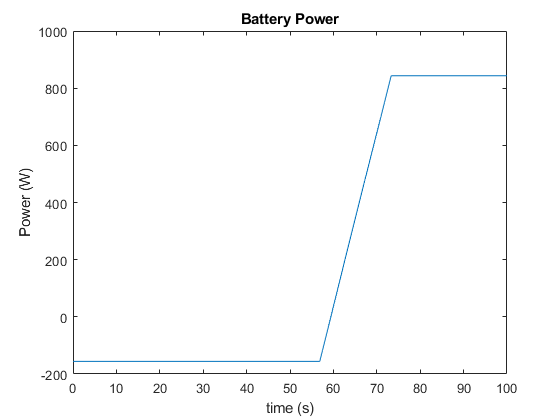


% new_plot(time_vector,voltage_batt,'Battery Voltage', 'time (s)', 'Voltage (V)')
% new_plot(time_vector,current_batt,'Battery Current', 'time (s)', 'Current (A)')
new_plot(time_vector,power_batt,'Battery Power', 'time (s)', 'Power (W)')

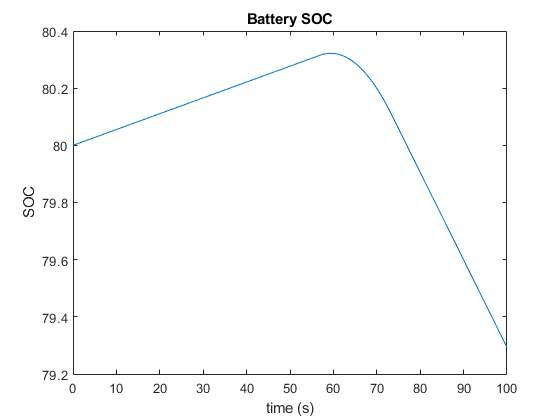

new_plot(time_vector,soc_batt,'Battery SOC', 'time (s)', 'SOC')